# Exercise 5: Prune the network to compress structurally

%% prune the trained network with data
% assumble the network to 
arrds = arrayDatastore(dataTable, "OutputType","same");
mbqTrain = minibatchqueue(arrds, OutputAsDlarray=1, MiniBatchFormat="SSBC"); 
npca = neuronPCA(net,mbqTrain,VerbosityLevel="steps");

Using solver mode "direct".
Computing covariance matrices for activations connected to: "conv_1/in"
Computing eigenvalues and eigenvectors for activations connected to: "conv_1/in"
Computing covariance matrices for activations connected to: "conv_1/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv_1/out"
Computing covariance matrices for activations connected to: "conv_2/in"
Computing eigenvalues and eigenvectors for activations connected to: "conv_2/in"
Computing covariance matrices for activations connected to: "conv_2/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv_2/out"
Computing covariance matrices for activations connected to: "conv_3/in"
Computing eigenvalues and eigenvectors for activations connected to: "conv_3/in"
Computing covariance matrices for activations connected to: "conv_3/out"
Computing eigenvalues and eigenvectors for activations connected to: "conv_3/out"
Computing covariance matrices for activations co

netProjected = compressNetworkUsingProjection(net,npca, "LearnablesReductionGoal",0.2); 

Compressed network has 21.9% fewer learnable parameters.
Projection compressed 4 layers: "conv_1","conv_2","conv_3","fc"


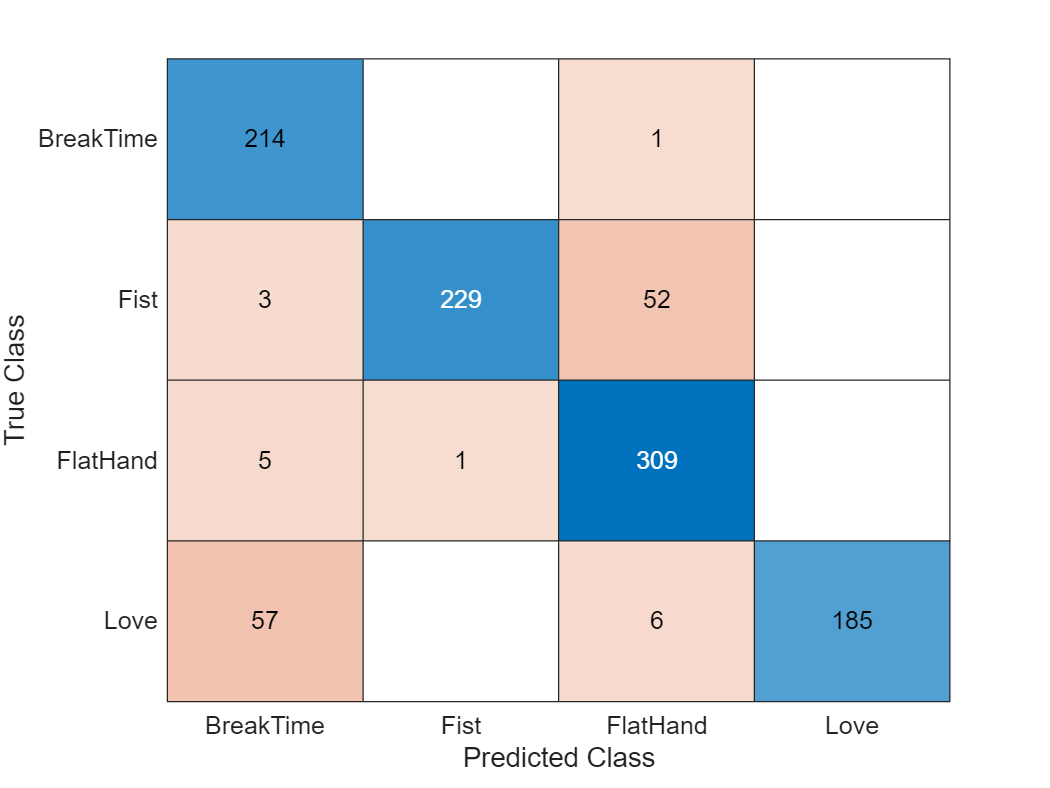

%% test the pruned network
scoresPruned = minibatchpredict(netProjected,xTest);
YPruned = onehotdecode(scoresPruned,classNames,2);
confusionchart(label_Test,YPruned);

accuracyPruned = mean(YPruned == label_Test) 

accuracyPruned = 0.8823


%% Export
exportONNXNetwork(netProjected, "net_Pruned.onnx"); 


## Try in Dev Cloud

web("https://stm32ai-cs.st.com/home"); 